# Lab 1

Ross Smyth

## Project 1

addpath('ADSP_ToolBox\')

h = [[0, 5]; [1, 3]];
% Run ctfgui
% Enter 5 for the Numerator
% Enter 1 3 for the Denominator
% Change Frequency to radians/sec
% Frequency limits to 0,20
% Export impulse to t_imp
% Export step to t_step
t_imp = '(5*exp(-3*t)).*ustep(t)';
t_step = '(-1.6667*exp(-3*t)+1.6667).*ustep(t)';

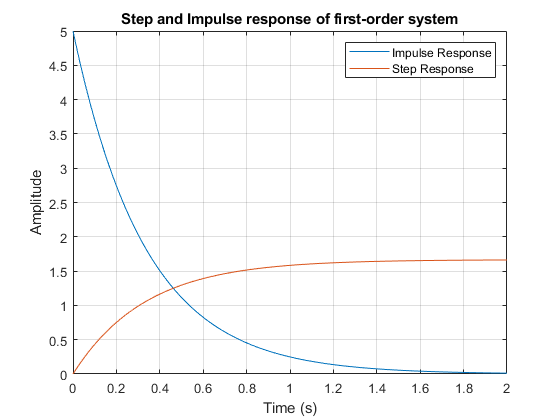

t = 0:0.01:2;
imp_res = eval(t_imp);
step_res = eval(t_step);

figure()
plot(t, imp_res, t, step_res)
xlabel('Time (s)')
ylabel('Amplitude')
legend('Impulse Response', 'Step Response')
title('Step and Impulse response of first-order system')
grid

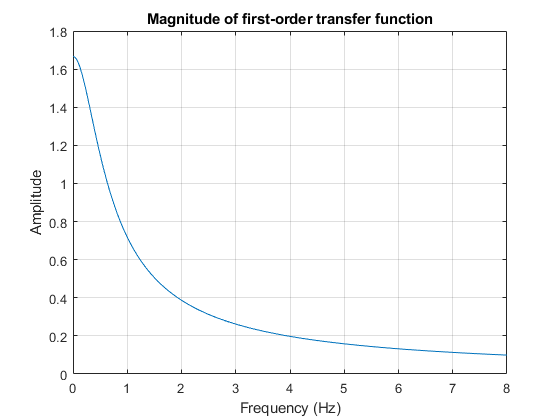

figure()
plot(freq, Mctf)
title('Magnitude of first-order transfer function')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
grid

% Run bodegui
% Enter the same transfer function

The asymtotic version of a bode plot can be useful to approximate the response of a system as a piecewise linear function, which can simpilify calculations while keeping error minimal. This can be used for example when calculating or using the transfer function of op-amps.

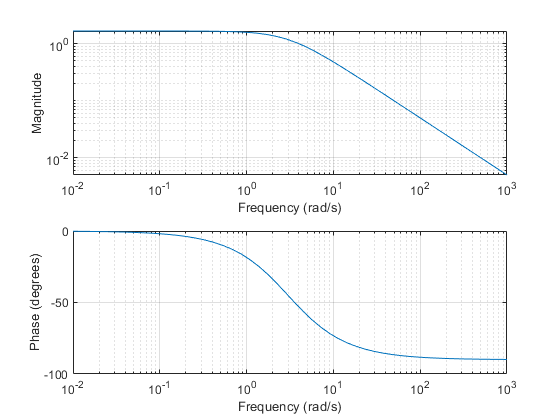

figure()
freqs([5], [1, 3], logspace(-2, 3))

fun_rise = trbw(h(1, :), h(2, :))

fun_rise =     0.7317
    1.0000
    0.4800


close % For some reason trbw tries to plot the freqs plot again.

theo_rise = 2.2 * 1 / h(2, 2)

theo_rise = 0.7333

perc_diff = 100 * (fun_rise(1) - theo_rise) / fun_rise(2)

perc_diff = -0.1667

#### f)

The settling time that was calculated from the function "trbw", part of the ADSP toolbox, is 1 second (the second element of the fun_rise vector). The theoretical rise time that is calculated by the standard 2.2 multiplied by the time constant is 0.73 seconds. This is a difference of less than 1% as seen above, which is a an insignificant amount. This means that the standard apporach by using he time constant is a good approximation.

## Project 2

### Part 1

clc, clear, close all

first_filter = [[1, -0.5]; [1, 0]];
relaxed_input  = [2, 0.6, 0, 0, 0, 0];
[first_tot, first_zs, ~] = sysresp1('z', first_filter(2, :), first_filter(1, :), relaxed_input, 0)

first_tot = '(12*(0.6 .^n)-10*(0.5 .^n)).*ustep(n)'

first_zs = '(12*(0.6 .^n)-10*(0.5 .^n)).*ustep(n)'

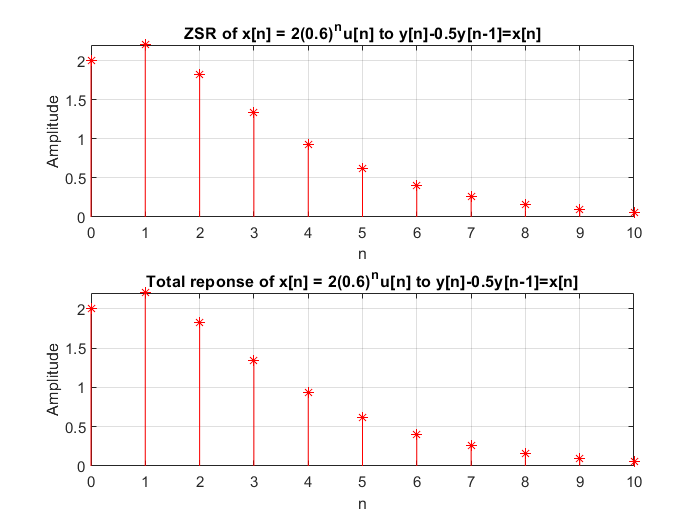

n = 0:1:10;

figure()
subplot(2, 1, 1)
first_zs = eval(first_zs);
dtplot(n, first_zs, '*')
title('ZSR of x[n] = 2(0.6)^nu[n] to y[n]-0.5y[n-1]=x[n]')
xlabel('n')
ylabel('Amplitude')
grid

subplot(2, 1, 2)
first_tot = eval(first_tot);
dtplot(n, first_tot, '*')
title('Total reponse of x[n] = 2(0.6)^nu[n] to y[n]-0.5y[n-1]=x[n]')
xlabel('n')
ylabel('Amplitude')
grid

The total response and the zero-state response are the same. This makes sense as the zero-state reponse of a filter is the response when the initial conditions are zero. Since the initial conditions are zero in this case, the ZSR is the total response.

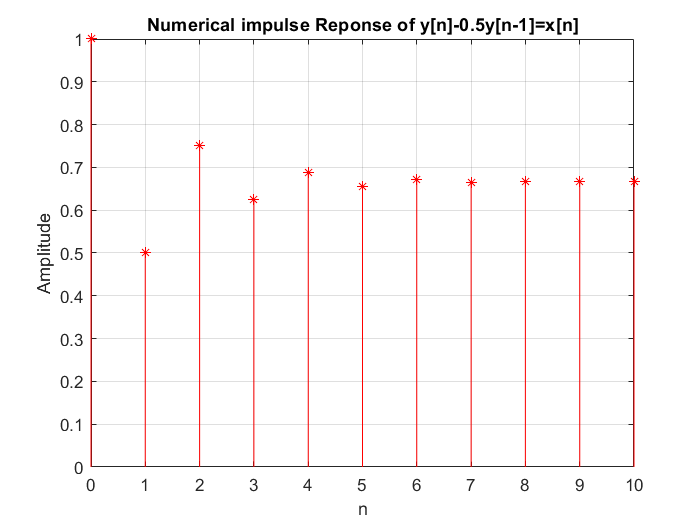

first_filter = [[1, 0.5]; [1, 0]];
filter_response = filter(first_filter(2, :), first_filter(1, :), ustep(n));

figure()
dtplot(n, filter_response, '*')
title('Numerical impulse Reponse of y[n]-0.5y[n-1]=x[n]')
xlabel('n')
ylabel('Amplitude')
grid

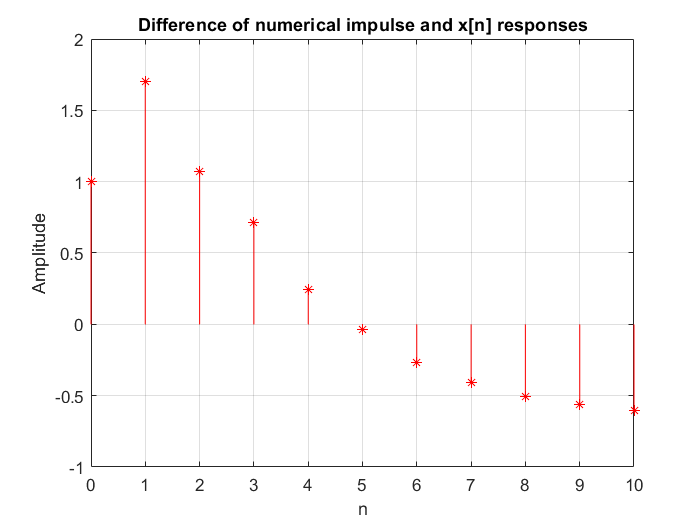

diff = first_zs - filter_response;
dtplot(n, diff, '*')
title('Difference of numerical impulse and x[n] responses')
xlabel('n')
ylabel('Amplitude')
grid

The difference is fairly significant, which is what I would expect as the inputs are two different signals. The first input is$x\left\lbrack n\right\rbrack =2{\left(0\ldotp 6\right)}^n u\left\lbrack n\right\rbrack$and the second input is just $x\left\lbrack n\right\rbrack =u\left\lbrack n\right\rbrack$. For the first input, the steady-state of the response seems to be zero or close to zero. For the second input the steady-state looks slightly below 0.7. During the transient period, the first input is rather smoothly asymtotic to it's steady-state. The second one instead oscillates around its steady-state value.

### Part 2

Step reponse and final value of $y\left\lbrack n\right\rbrack -1\ldotp 4y\left\lbrack n-1\right\rbrack +\textrm{Cy}\left\lbrack n-2\right\rbrack =x\left\lbrack n\right\rbrack$ for several different values of C, tabulated below.

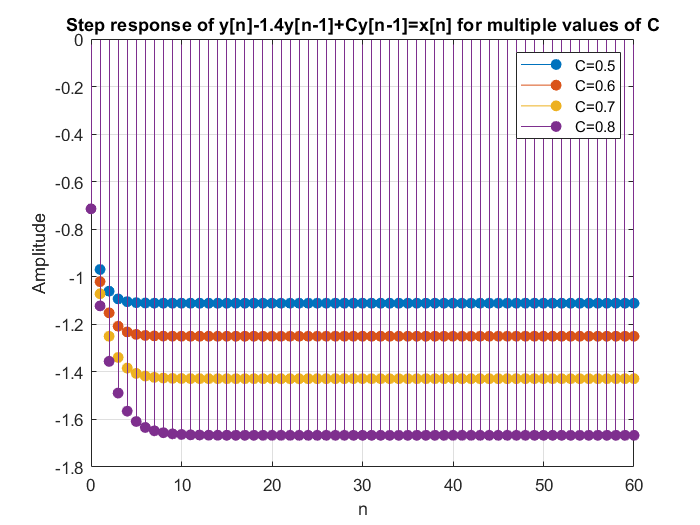

clc, clear, close all
sec_ord = [[-1.4, 0.5]; [1, 0]];
input   = [1, 1, 0, 0, 0, 0]; % Step response
n = 0:1:60;

resp_1 = sysresp1('z', sec_ord(2, :), sec_ord(1, :), input);
resp_1 = eval(resp_1);

sec_ord(1, 2) = 0.6;
resp_2 = sysresp1('z', sec_ord(2, :), sec_ord(1, :), input);
resp_2 = eval(resp_2);

sec_ord(1, 2) = 0.7;
resp_3 = sysresp1('z', sec_ord(2, :), sec_ord(1, :), input);
resp_3 = eval(resp_3);

sec_ord(1, 2) = 0.8;
resp_4 = sysresp1('z', sec_ord(2, :), sec_ord(1, :), input);
resp_4 = eval(resp_4);

stem(n', [resp_1', resp_2', resp_3', resp_4'], 'filled')
title('Step response of y[n]-1.4y[n-1]+Cy[n-1]=x[n] for multiple values of C')
xlabel('n')
ylabel('Amplitude')
legend('C=0.5', 'C=0.6', 'C=0.7', 'C=0.8')
grid

C = [0.5, 0.6, 0.7, 0.8];
fin = [resp_1(end),resp_2(end), resp_3(end), resp_4(end)];
Damping = {'Overdamped', 'Overdamped', 'Overdamped', 'Overdamped'};
Final_values = table(C', fin', Damping', 'VariableNames', {'C', 'Final_Value', 'Damping'})

Final_values = 4×3 table
     C     Final_Value       Damping    
    ___    ___________    ______________

    0.5      -1.1111      {'Overdamped'}
    0.6        -1.25      {'Overdamped'}
    0.7      -1.4286      {'Overdamped'}
    0.8      -1.6667      {'Overdamped'}


By inspection, all of the response signals look to be overdamped. I wouldn't expect this, as I would expect the assignment to be more interesting but that is what I see.

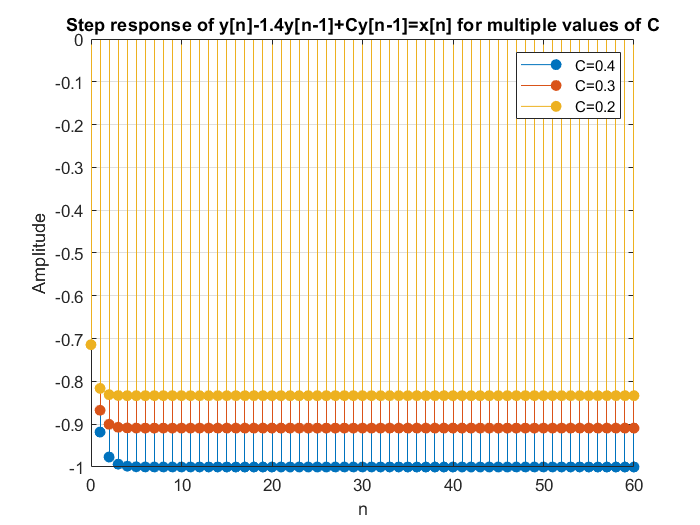

sec_ord(1, 2) = 0.4;
resp_5 = sysresp1('z', sec_ord(2, :), sec_ord(1, :), input);
resp_5 = eval(resp_5);

sec_ord(1, 2) = 0.3;
resp_6 = sysresp1('z', sec_ord(2, :), sec_ord(1, :), input);
resp_6 = eval(resp_6);

sec_ord(1, 2) = 0.2;
resp_7 = sysresp1('z', sec_ord(2, :), sec_ord(1, :), input);
resp_7 = eval(resp_7);

stem(n', [resp_5', resp_6', resp_7'], 'filled')
title('Step response of y[n]-1.4y[n-1]+Cy[n-1]=x[n] for multiple values of C')
xlabel('n')
ylabel('Amplitude')
legend('C=0.4', 'C=0.3', 'C=0.2')
grid

As the value of C is increased in the difference equation, the final value decreases. It is not linear, as it is obvious to see that as each time C increases by 0.1 the final value decreases non-linearly.

eq_roots = [];
for i=0.2:0.1:0.8
    eq_roots(end + 1, :) = roots([1, -1.4, i]);
end
eq_roots = abs(eq_roots);
root_stab = all(eq_roots < 1, 2);

Stability = table([0.2:0.1:0.8]', root_stab, 'VariableNames', {'C', 'Stable'})

Stability = 7×2 table
     C     Stable
    ___    ______

    0.2    false 
    0.3    false 
    0.4    true  
    0.5    true  
    0.6    true  
    0.7    true  
    0.8    true  


As shown in the table above, for the values of C equal 0.2 and 0.3, according the to the stability criterion of the Z-transform the reponses should be unstable. I do not see any obvious instability in the response plot. It may be that the instability is minimal, as it just crossed the transition from stable to unstablt, and it would take a larger domain to see.